clear;
close all;

CSI_B=load("CSI2.mat","CSI");
CSI_B=CSI_B.CSI;
CSI_C=load("CSI3.mat","CSI");
CSI_C=CSI_C.CSI;

%定义一些值
sampfreq=8e7; %80MHz
midfreq=5.1*1e9; %5.1GHz
freqspace=sampfreq/256;

c=3e8;
d=0.5;

source = 1; % 信源数目
snapshot = 512; %快拍数

%提取7-127列
CSI_B_Use=CSI_B(:, 7:126);
CSI_C_Use=CSI_C(:, 7:126);

% 定义子阵列大小
rows = 2;
cols = 15;

% 定义滑动步长
row_step = 1;
col_step = 1;

% 初始化结果矩阵
X = [];

%矩阵大小
[total_rows, total_cols] = size(CSI_B_Use);

%遍历上半部分子阵列
for row_start=1:row_step:(total_rows - rows + 1)
    for col_start = 1:col_step:(total_cols - cols + 1)
        %提取子阵列
        sub_array = CSI_B_Use(row_start:(row_start+rows-1), col_start:(col_start + cols - 1));

        %转置并转为列向量
        col_vector = sub_array.';
        col_vector = col_vector(:);

        %拼接到矩阵 X
        X = [X, col_vector];
    end
end

% 检查生成矩阵的大小
disp(size(X)); % 应该为 [rows*cols, total_num_vectors]

    30   742



attena = rows;%子阵列行数/天线
subcarrier = cols;%子阵列列数/子载波

% 计算接收信号的协方差矩阵
R = X * X'; 

% 对协方差矩阵进行特征分解
[E, D] = eig(R);
[eigenvalues, idx] = sort(diag(D), 'descend');

E = E(:,idx);
P = sum(eigenvalues);                           % 接收数据的总功率
P_cum = cumsum(eigenvalues);                    % 累积特征值
J = find((P_cum)/P>=0.95);                      % 选择主要分量的数量
J = J(1);                                       % 选择第一个满足条件的分量
Es = E(:,source+1:end);                              % 噪声子空间

% 定义搜索空间
theta_scan = -90:0.1:90; % 扫描角度范围-180-180
tau_scan = -1e-7:1e-9:1e-7; % 扫描时间延迟范围1ns-100ns

P_music = zeros(length(theta_scan), length(tau_scan)); % 初始化伪谱矩阵

% 计算频率响应
Omega = @(tau) exp(-1i * 2 * pi * tau * freqspace);

% 计算角度响应
Phi = @(theta) exp(-1i * 2 * pi * (0:attena-1).' * d* sind(theta));


for i = 1:length(theta_scan)
    % 计算当前扫描角度的角度响应矩阵
    a_theta_matrix = Phi(theta_scan(i));
    
    for j = 1:length(tau_scan)
        % 计算时间延迟响应
        a_tau = Omega(tau_scan(j)).^(0:(subcarrier-1))';
        
        % 克罗内克积生成联合导向向量
        a_scan = kron(a_theta_matrix, a_tau); 
        
        % 计算伪谱值
        P_music(i, j) = 1 / (a_scan' * (Es * Es') * a_scan);
    end
end

% 找到伪谱函数的最大值
[max_value, max_index] = max(P_music(:));
[theta_index, tau_index] = ind2sub(size(P_music), max_index);
estimated_theta = theta_scan(theta_index);
estimated_tau = tau_scan(tau_index);

% 显示估计结果
fprintf('Estimated AoA: %.2f degrees\n', estimated_theta);

Estimated AoA: 0.60 degrees


fprintf('Estimated ToF: %.2e seconds\n', estimated_tau);

Estimated ToF: -3.60e-08 seconds


% 计算归一化后的MUSIC伪谱 (以dB为单位)
P_music_dB = 10*log10(abs(P_music) / max(max(abs(P_music))));

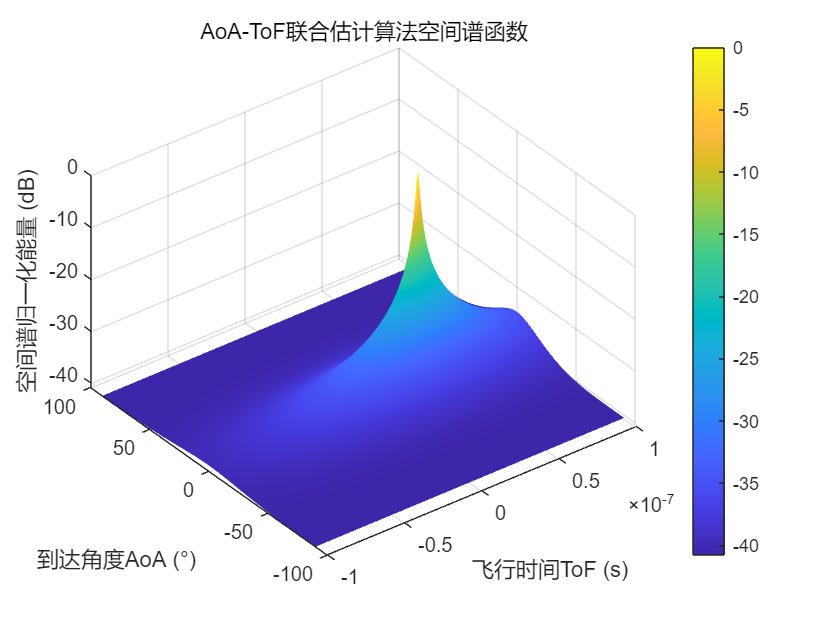

% 绘制三维MUSIC伪谱
figure;
surf(-tau_scan, theta_scan, P_music_dB, 'EdgeColor', 'none'); % 三维显示伪谱
xlabel('飞行时间ToF (s)');
ylabel('到达角度AoA (°)');
zlabel('空间谱归一化能量 (dB)');
title('AoA-ToF联合估计算法空间谱函数');
colorbar; % 添加颜色条
view(-37.5, 45); % 默认视角